clear all; clc; close all;

## Simple swing-up script:

% literally just applied the input toward the 
% direction of angular velocity
N  = 1500;
h = 0.01;
t  = (0:N-1) * h;
xk = [0.1; 0.01; 0.1];

% current identified parameters
A = [0.9896 0 0; 0 1 0.01; -0.0001 -0.268 0.9989];
B = [4.2052; 0; 0];
C = [1 0 0; 0 1 0];
D = [0; 0];

xrec = zeros(3, N);

% copy pasted simSystem_sin here (per iteration)
A_nl      = A;
A_nl(3,2) = 0;
A_sin     = [0 0 0; 0 0 0; 0 A(3,2) 0];

for i = 1:N
    if xk(2) < 0
        uk = -1;
    else
        uk = 1;
    end
    xk = A_nl * xk + B * uk + A_sin * sin(xk);
    xrec(:,i) = xk;
end

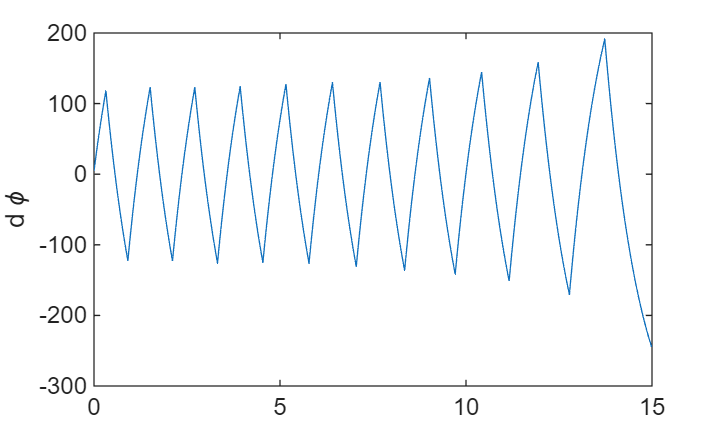

% plot the 
figure; plot(t, xrec(1,:)); ylabel('d \phi');

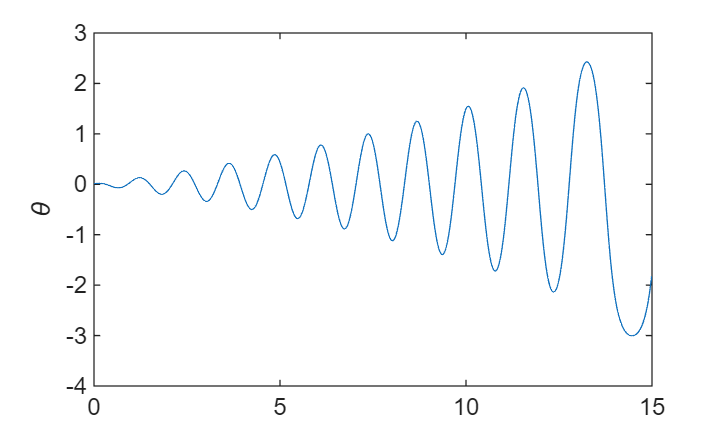

figure; plot(t, xrec(2,:)); ylabel('\theta');

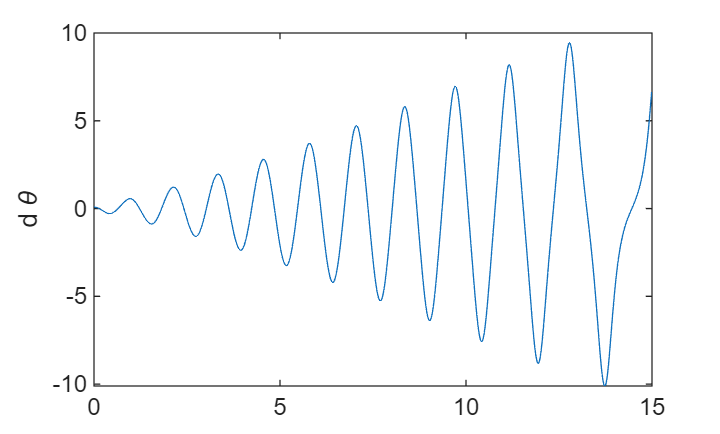

figure; plot(t, xrec(3,:)); ylabel('d \theta');

## LQR Controller:

N  = 1500;
Q = zeros(3,3); Q(2,2) = 100;
R = 0.001;
% find feedback control law
[K, S, P] = dlqr(A,B,Q,R);

% simulate
xk = [0; pi+0.15; 0];
xrec = zeros(3, N);
urec = zeros(N,1);
thetaref = pi;
xref = [0; thetaref; 0];

for i = 1:N
    e = xk - xref;
    uk = -K * e;
    xk = A_nl * xk + B * uk + A_sin * sin(xk);
    xrec(:,i) = xk;
    urec(i) = uk;
end

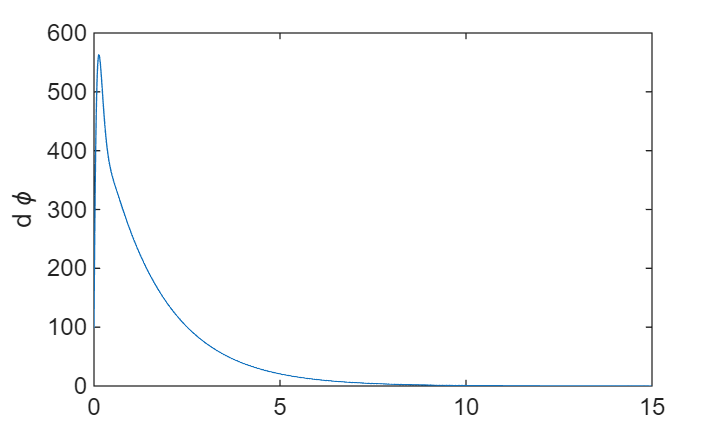

figure; plot(t, xrec(1,:)); ylabel('d \phi');

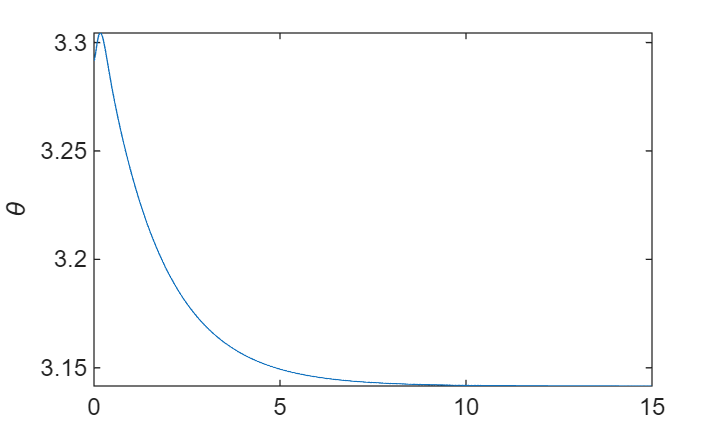

figure; plot(t, xrec(2,:)); ylabel('\theta');

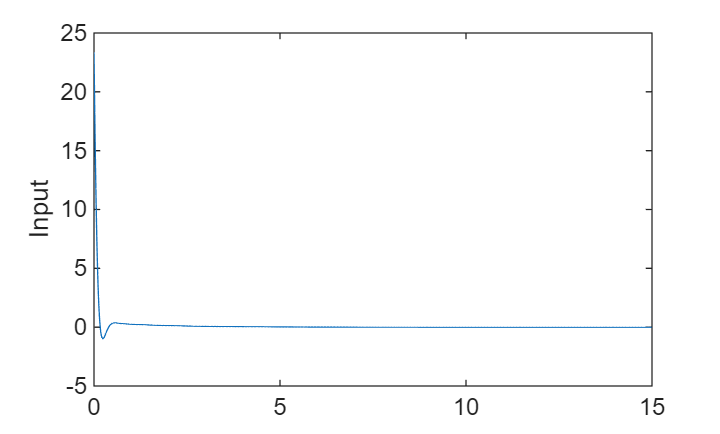

%figure; plot(t, xrec(3,:)); ylabel('d \theta');
figure; plot(t, urec); ylabel('Input');

## Energy-based swing up control:

Hopefully this arrives at the equilibrium at a relatively low angular velocity relative to the first version.

N = 5000;
h = 0.01;
t = (0:N-1) * h;
xk = [0.1; 0.01; 0.1];

A = [0.9896 0 0; 0 1 0.01; -0.0001 -0.268 0.9989];
B = [4.2052; 0; 0];
C = [1 0 0; 0 1 0];
D = [0; 0];

xrec = zeros(3, N);

A_nl = A;
A_nl(3,2) = 0;
A_sin = [0 0 0; 0 0 0; 0 A(3,2) 0];

% Energy-based swing-up parameters
% Extract continuous-time pendulum params from discrete A matrix
g_eff = A(3,2) / (-h);        % effective g/l from identified A(3,2)
E_ref = g_eff;                 % energy at upright equilibrium (cos(pi) = -1 → E_ref = g_eff * (1 - (-1)) / 2... 
% Using potential energy: E = g_eff*(1 - cos(theta)), E_ref at top = 2*g_eff
E_ref = 2 * g_eff;
k_e = 0.5;                     % energy injection gain (tune as needed)

for i = 1:N
    theta  = xk(2);
    dtheta = xk(3);

    % Pendulum energy (relative to hanging down equilibrium)
    E = 0.5 * dtheta^2 + g_eff * (1 - cos(theta));

    % Energy error, scaled by angular velocity direction
    uk = k_e * (E - E_ref) * sign(dtheta);

    % Saturate to [-1, 1]
    uk = max(-1, min(1, uk));

    xk = A_nl * xk + B * uk + A_sin * sin(xk);
    xrec(:,i) = xk;
end

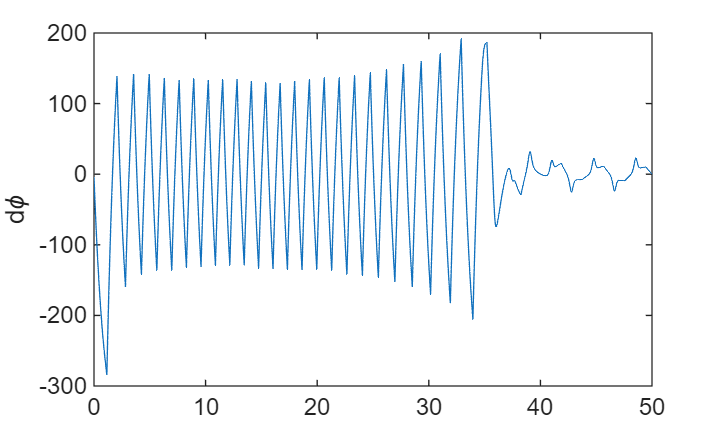

figure; plot(t, xrec(1,:)); ylabel('d\phi');

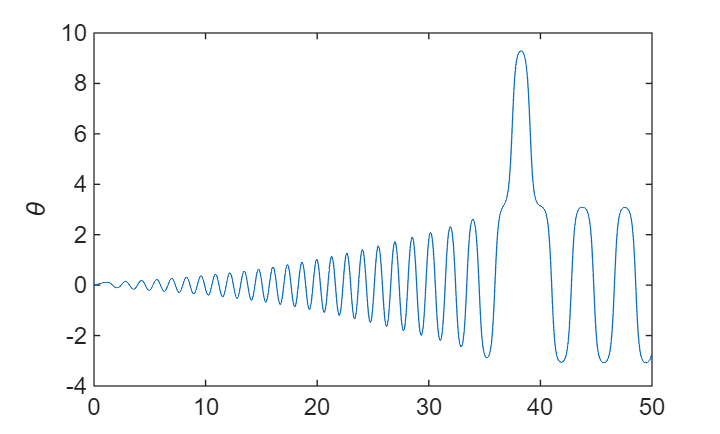

figure; plot(t, xrec(2,:)); ylabel('\theta');

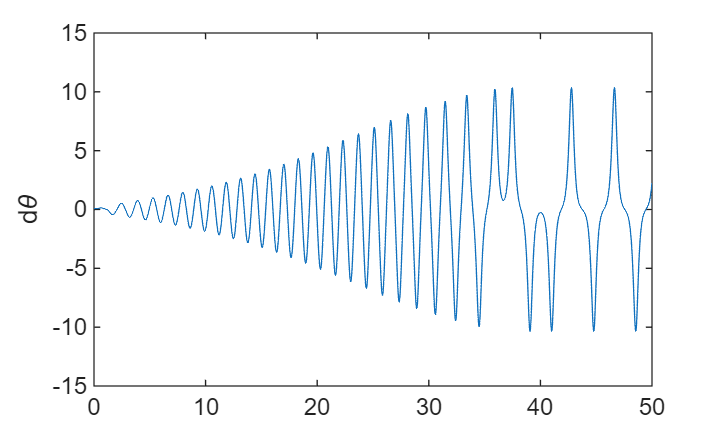

figure; plot(t, xrec(3,:)); ylabel('d\theta');

## Combine the two control methods:

See if it works...

N = 5000;
h = 0.01;
t = (0:N-1) * h;
xk = [0.1; 0.01; 0.1];

A = [0.9896 0 0; 0 1 0.01; -0.0001 -0.268 0.9989];
B = [4.2052; 0; 0];
C = [1 0 0; 0 1 0];
D = [0; 0];

xrec = zeros(3, N);

A_nl = A;
A_nl(3,2) = 0;
A_sin = [0 0 0; 0 0 0; 0 A(3,2) 0];

% Energy-based swing-up parameters
% Extract continuous-time pendulum params from discrete A matrix
g_eff = A(3,2) / (-h);        % effective g/l from identified A(3,2)
E_ref = g_eff;                 % energy at upright equilibrium (cos(pi) = -1 → E_ref = g_eff * (1 - (-1)) / 2... 
% Using potential energy: E = g_eff*(1 - cos(theta)), E_ref at top = 2*g_eff
E_ref = 2 * g_eff;
k_e = 0.5;                     % energy injection gain (tune as needed)

for i = 1:N
    if ((pi-0.2)<xk(2))&&(xk(2)<(pi+0.2))
    %LQR
        e = xk - xref;
        uk = -K * e;
    else
    % Swing up
    theta  = xk(2);
    dtheta = xk(3);

    E = 0.5 * dtheta^2 + g_eff * (1 - cos(theta));

    uk = k_e * (E - E_ref) * sign(dtheta);
    uk = max(-1, min(1, uk));  

    end

    xk = A_nl * xk + B * uk + A_sin * sin(xk);
    xrec(:,i) = xk;
end

## Dope ass animation:

Run this with any of the xrec vectors from previous sections to visualize whats happening to our virtual setup yadigg

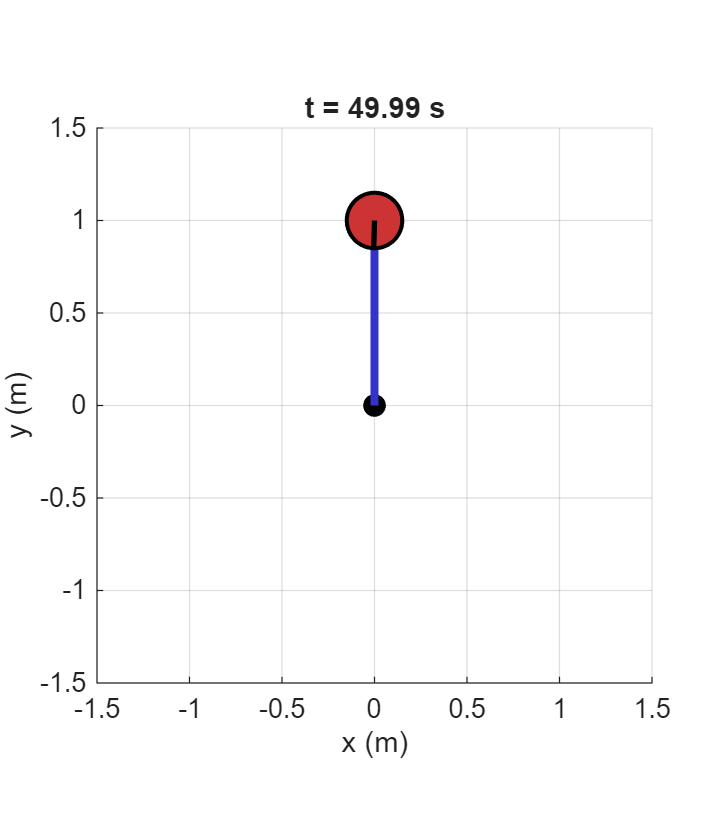

%% Animation
L       = 1;        % visual rod length (meters) — adjust to taste
r_wheel = 0.15;     % visual flywheel radius
fps     = 30;       % animation frame rate
skip    = max(1, round(1/(fps*h)));   % only draw every nth step

figure('Color','w','Position',[100 100 600 700]);
ax = axes;
axis equal; hold on; grid on;
xlim([-1.5*L, 1.5*L]);
ylim([-1.5*L, 1.5*L]);
xlabel('x (m)'); ylabel('y (m)');
title('Reaction Wheel Pendulum');

% Draw pivot point
plot(0, 0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);

% Initial geometry
theta0 = xrec(2, 1);   % theta: 0 = down, pi = up
% Convert: 0=down means tip is at (0,-L) when theta=0
% x_tip = L*sin(theta), y_tip = -L*cos(theta)
x_tip = L * sin(theta0);
y_tip = -L * cos(theta0);

% Create graphical objects
h_rod   = line([0, x_tip], [0, y_tip], ...
               'Color', [0.2 0.2 0.8], 'LineWidth', 3);

h_wheel = rectangle('Position', [x_tip - r_wheel, y_tip - r_wheel, ...
                                  2*r_wheel, 2*r_wheel], ...
                    'Curvature', [1 1], ...
                    'FaceColor', [0.8 0.2 0.2], ...
                    'EdgeColor', 'k', 'LineWidth', 1.5);

% Spoke on flywheel to show rotation
phi_dot = xrec(1, 1);
phi_accum = 0;   % integrate phi_dot to get phi angle for visual
h_spoke = line([x_tip, x_tip + r_wheel*cos(phi_accum)], ...
               [y_tip, y_tip + r_wheel*sin(phi_accum)], ...
               'Color', 'k', 'LineWidth', 2);

h_time = title(sprintf('t = %.2f s', 0));

%% Run animation
for i = 1:skip:N
    theta   = xrec(2, i);
    phi_dot_i = xrec(1, i);

    % Pendulum tip position
    x_tip = L * sin(theta);
    y_tip = -L * cos(theta);

    % Accumulate flywheel angle from phi_dot
    phi_accum = phi_accum + phi_dot_i * h * skip;

    % Update rod
    set(h_rod, 'XData', [0, x_tip], 'YData', [0, y_tip]);

    % Update flywheel disc
    set(h_wheel, 'Position', [x_tip - r_wheel, y_tip - r_wheel, ...
                               2*r_wheel, 2*r_wheel]);

    % Update spoke (shows flywheel spinning)
    set(h_spoke, 'XData', [x_tip, x_tip + r_wheel*cos(phi_accum)], ...
                 'YData', [y_tip, y_tip + r_wheel*sin(phi_accum)]);

    set(h_time, 'String', sprintf('t = %.2f s', i*h));
    drawnow limitrate;
    pause(h*skip);
end